# Filter Quality Analysis

Fs = 1000;
freq_range = [100,200];
filt10 = fir1(10,freq_range/(Fs/2));
filt100 = fir1(100,freq_range/(Fs/2));
filt1000 = fir1(1000,freq_range/(Fs/2));


## Window 10

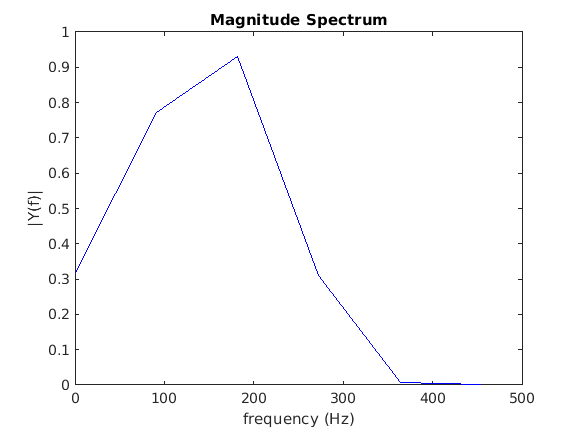

[yfft,f]=myfft(filt10,Fs);
MagnitudeSpectrumPlot(yfft,f);

[~,i1] = min(abs(f-90));
abs(yfft(i1))

ans = 0.7722

## Window 100

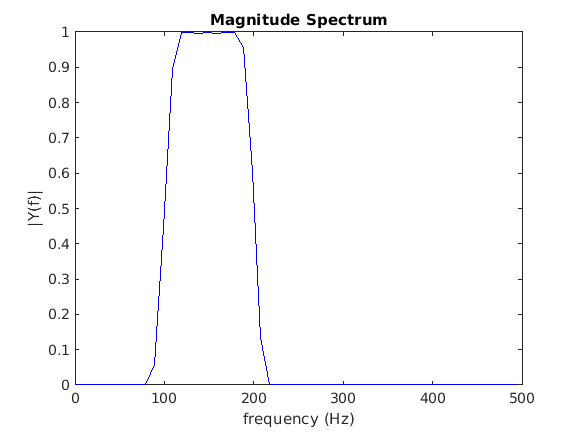

[yfft,f]=myfft(filt100,Fs);
MagnitudeSpectrumPlot(yfft,f);

[~,i2] = min(abs(f-90));
abs(yfft(i2))

ans = 0.0594

## Window 1000

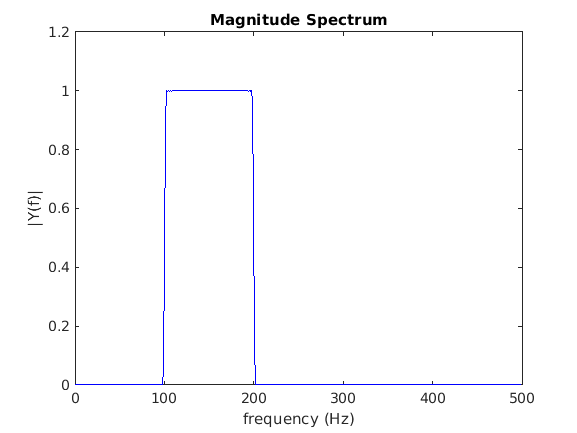

[yfft,f]=myfft(filt1000,Fs);
MagnitudeSpectrumPlot(yfft,f);

[~,i3] = min(abs(f-90));
abs(yfft(i3))

ans = 6.8140e-04